addpath('C:\Users\prakh\Documents\MATLAB\saved');  
rng(42);

%% 1)Trajectory Data (Lat/Lon)
filename = '09 - 2023-12-08-09-10-46_SRCC_Snow_speed_20250212170056.asc'; 
trajData = readtable(filename);
latVec_all = trajData.Var2;
lonVec_all = trajData.Var3;
nPointsAll = numel(latVec_all);

%% 2) Base Stations (Lat/Lon)
BS_S1_lat = 50.53495;
BS_S1_lon = 12.872275;

BS_S2_lat = 50.533847;
BS_S2_lon = 12.806614;

BS_S3_lat = 50.5400;  
BS_S3_lon = 12.8400;

BS_S4_lat = 50.5300;
BS_S4_lon = 12.8400;

BS_S5_lat = 50.5500;
BS_S5_lon = 12.8900;

BSpositions_latlon = [
    BS_S1_lat, BS_S1_lon;
    BS_S2_lat, BS_S2_lon;
    BS_S3_lat, BS_S3_lon;
    BS_S4_lat, BS_S4_lon;
    %BS_S5_lat, BS_S5_lon
];
nBS = size(BSpositions_latlon, 1);

%% 3) 3GPP Scenario Parameters
scenario = 'uma';
simParams = struct( ...
    'txPower',    40, ...  % [dBm]
    'txGain',     15, ...  % [dBi]
    'rxGain',     0, ...
    'systemLoss', 0, ...
    'fHz',        3.5e9, ...
    'fGHz',        3.5, ...
    'hBS',        25, ...
    'hUT',        1.5, ...
    'h',          25, ...
    'd0',         1 ...
);

% Calculate d_bp for the scenario
c = physconst('LightSpeed');
simParams.d_bp = (4 * (simParams.hBS - 1) * (simParams.hUT - 1) * simParams.fHz) / c;
fprintf('Breakpoint distance d_bp = %.2f m\n', simParams.d_bp);

Breakpoint distance d_bp = 560.39 m



%% 4) Calculate Distance to Each BS (Using Haversine)
minDistArray = zeros(nPointsAll, 1);
for i = 1:nPointsAll
    distsToAllBS = haversine([latVec_all(i), lonVec_all(i)], BSpositions_latlon);
    minDistArray(i) = min(distsToAllBS);
end

%% 5) Filter Points within Coverage
maxRange_m = 5000;
inCoverageMask = (minDistArray <= maxRange_m);

% in-range points
latVec_inRange = latVec_all(inCoverageMask);
lonVec_inRange = lonVec_all(inCoverageMask);
nPointsIn = sum(inCoverageMask);

fprintf('Kept %d points (%.1f%%) within %.1f km of at least one BS.\n', ...
    nPointsIn, 100*nPointsIn/nPointsAll, maxRange_m/1000);

Kept 5119 points (32.6%) within 5.0 km of at least one BS.



%% 6) Calculate 3GPP RSSI for In-Range Points
rssiMatrix_in = zeros(nPointsIn, nBS);

for i = 1:nPointsIn
    tgtPos = [latVec_inRange(i), lonVec_inRange(i)];  % user lat/lon
    for b = 1:nBS
        anchorPos = BSpositions_latlon(b, :);
        [rssiVal, ~] = calculateRSSI_3GPP(anchorPos, tgtPos, simParams, scenario);
        rssiMatrix_in(i, b) = rssiVal;
    end
end

% Max RSSI
rssiVec_in = max(rssiMatrix_in, [], 2);

%% 7) Invert RSSI to Distance
estDistMatrix_in = zeros(nPointsIn, nBS);
trueDistMatrix   = zeros(nPointsIn, nBS); % actual dist using haversine

for i = 1:nPointsIn
    tgtPos = [latVec_inRange(i), lonVec_inRange(i)];  % User lat/lon
    
    for b = 1:nBS
        anchorPos = BSpositions_latlon(b, :);

        % Calculate d2D using the Haversine formula
        d2D = haversine(tgtPos, anchorPos);
        trueDistMatrix(i,b) = d2D;

        % Now call rssi2distance_LogNormal with d2D
        estDistMatrix_in(i, b) = rssi2distance_LogNormal(rssiMatrix_in(i, b), simParams, scenario, d2D);
    end
end

%% 8) Initial Estimate for RLS
anchorPos2D = [BSpositions_latlon(:,1)'; BSpositions_latlon(:,2)'];
truePosMatrix_in = [latVec_inRange'; lonVec_inRange'];

[estPosLS_in, rmseLS_in, ~] = estimatePositionUsingLS_batchVectorized( ...
    anchorPos2D, estDistMatrix_in, truePosMatrix_in);

avgRMSE_LS_in = mean(rmseLS_in);
fprintf('Mean Initial guess RMSE (In-Range Only): %.2f m\n', avgRMSE_LS_in);

Mean Initial guess RMSE (In-Range Only): 222200886918.26 m



%% 9) RLS
nPointsIn = size(estPosLS_in, 2);
rlsEstimates_in = zeros(2, nPointsIn);
rmseRLS_in      = zeros(1, nPointsIn);
resnormCells_in = cell(1, nPointsIn);
rmseIterCells_in= cell(1, nPointsIn);

for i = 1:nPointsIn
    observedRanges_i = estDistMatrix_in(i, :);
    tgtpos2D_i       = truePosMatrix_in(:, i);
    
    % initial guess
    lsInit_i = estPosLS_in(:, i);

    [mu_i, rmse_i, resnorm_vec_i, rmse_vec_i] = ...
        recursiveLeastSquares(anchorPos2D, observedRanges_i, tgtpos2D_i, lsInit_i);

    rlsEstimates_in(:, i) = mu_i;
    rmseRLS_in(i)         = rmse_i;
    resnormCells_in{i}    = resnorm_vec_i;
    rmseIterCells_in{i}   = rmse_vec_i;
end

avgRMSE_RLS_in = mean(rmseRLS_in);
fprintf('Mean RLS RMSE (In-Range): %.2f m\n', avgRMSE_RLS_in);

Mean RLS RMSE (In-Range): 3867.72 m


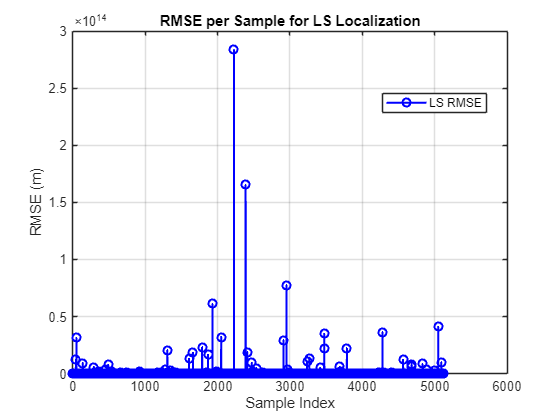


%% RMSE per Sample for LS
figure('Color','white','Name','RMSE per Sample - LS');
plot(1:length(rmseLS_in), rmseLS_in, 'bo-', 'LineWidth', 1.5);
xlabel('Sample Index');
ylabel('RMSE (m)');
title('RMSE per Sample for LS Localization');
grid on;
legend('LS RMSE', 'Location', 'best');

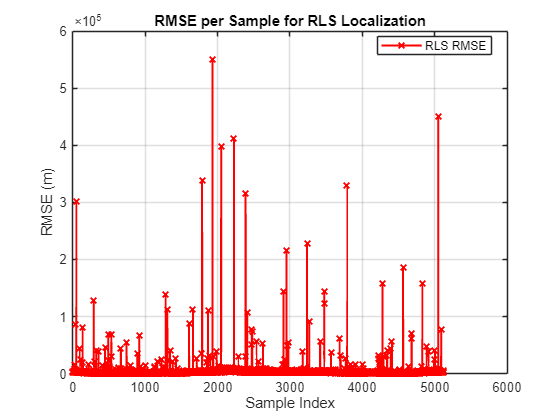


%% RMSE per Sample for RLS
figure('Color','white','Name','RMSE per Sample - RLS');
plot(1:length(rmseRLS_in), rmseRLS_in, 'rx-', 'LineWidth', 1.5);
xlabel('Sample Index');
ylabel('RMSE (m)');
title('RMSE per Sample for RLS Localization');
grid on;
legend('RLS RMSE', 'Location', 'best');

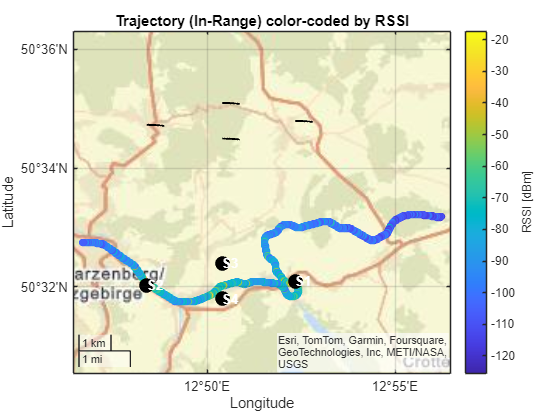


%% 1. Plot In-Range Trajectory (Color-coded by RSSI)
figure('Color','white','Name','In-Range Coverage');
gx = geoaxes;
geobasemap(gx, 'streets');
hold(gx, 'on');

% Plot the true trajectory color-coded by RSSI
geoscatter(gx, latVec_inRange, lonVec_inRange, 30, rssiVec_in, 'filled');
cb = colorbar;
cb.Label.String = 'RSSI [dBm]';
title(gx, 'Trajectory (In-Range) color-coded by RSSI');

% Plot the base stations as black circles
geoscatter(gx, BSpositions_latlon(:,1), BSpositions_latlon(:,2), 120, 'k', 'filled');
for b = 1:nBS
    text(gx, BSpositions_latlon(b,1), BSpositions_latlon(b,2), sprintf('S%d', b),...
        'FontWeight', 'bold', 'Color', 'w');
end

% Number of points to draw a smooth circle
nCirclePoints = 100;
theta = linspace(0, 2*pi, nCirclePoints);

% Plot the coverage circles for each BS
for i = 1:nBS
    % Get center point for the BS
    centerLat = BSpositions_latlon(i, 1);
    centerLon = BSpositions_latlon(i, 2);

    % Calculate the circle points directly in Lat/Lon
    circleLat = zeros(1, nCirclePoints);
    circleLon = zeros(1, nCirclePoints);

    for j = 1:nCirclePoints
        % Calculate the endpoint for each angle using the Haversine function
        [circleLat(j), circleLon(j)] = endpointHaversine(centerLat, centerLon, maxRange_m, theta(j));
    end

    % Plot the coverage circle
    geoplot(gx, circleLat, circleLon, 'k-', 'LineWidth', 1.5);
end

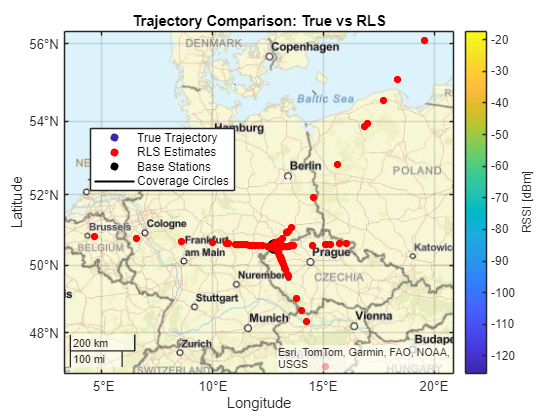


%% 2. Plot In-Range Trajectory with RLS Estimates
%% Define Coverage Circle Parameters (if not already defined)
maxRange_m = 5000;        % 5 km coverage radius in meters
nCirclePoints = 100;      % Number of points to draw a smooth circle
theta = linspace(0, 360, nCirclePoints); % Angles in degrees

%% 2. Plot In-Range Trajectory with RLS Estimates
figure('Color','white','Name','RLS Estimated Trajectory');
gx = geoaxes;
geobasemap(gx, 'streets');
hold(gx, 'on');

% Plot the true trajectory color-coded by RSSI
hTrue = geoscatter(gx, latVec_inRange, lonVec_inRange, 30, rssiVec_in, 'filled');
cb = colorbar;
cb.Label.String = 'RSSI [dBm]';
title(gx, 'Trajectory Comparison: True vs RLS');

% Plot the base stations as black circles
hBS = geoscatter(gx, BSpositions_latlon(:,1), BSpositions_latlon(:,2), 120, 'k', 'filled');
for b = 1:nBS
    text(gx, BSpositions_latlon(b,1), BSpositions_latlon(b,2), sprintf('S%d', b),...
         'FontWeight', 'bold', 'Color', 'w');
end

% Plot the coverage circles for each base station
hCoverage = gobjects(nBS,1); % Preallocate graphic object array for legend
for i = 1:nBS
    % Get center point for the BS
    centerLat = BSpositions_latlon(i, 1);
    centerLon = BSpositions_latlon(i, 2);

    % Calculate the circle points directly in lat/lon using the endpointHaversine function
    circleLat = zeros(1, nCirclePoints);
    circleLon = zeros(1, nCirclePoints);
    for j = 1:nCirclePoints
        [circleLat(j), circleLon(j)] = endpointHaversine(centerLat, centerLon, maxRange_m, theta(j));
    end

    % Plot the coverage circle (red line for clarity; adjust color as needed)
    hCoverage(i) = geoplot(gx, circleLat, circleLon, 'k-', 'LineWidth', 1.5);
end

% Convert RLS estimates from local XY to lat/lon using the first base station as reference
latRef = BSpositions_latlon(1,1);
lonRef = BSpositions_latlon(1,2); 
[estLat, estLon] = localXY2LatLon(rlsEstimates_in(1,:), rlsEstimates_in(2,:), latRef, lonRef);

% Overlay the RLS-estimated trajectory in red
hRLS = geoscatter(gx, estLat, estLon, 30, 'r', 'filled');

% Add a legend (order: True Trajectory, RLS Estimates, Base Stations, Coverage Circles)
legend(gx, [hTrue, hRLS, hBS, hCoverage(1)], ...
       {'True Trajectory', 'RLS Estimates', 'Base Stations', 'Coverage Circles'}, ...
       'Location', 'best');

%coverage plot
anchorpos3D = [anchorPos2D; zeros(1, size(anchorPos2D, 2))];

numBS = size(anchorpos3D, 2);
txs   = txsite.empty;  % preallocate array of txsite objects

%power in watts
P_Watt = 10^((simParams.txPower - 30)/10);

for iBS = 1:numBS
    txs(iBS) = txsite("Name",          sprintf("BS_%d", iBS), ...
                      "Latitude",      anchorpos3D(1, iBS), ...
                      "Longitude",     anchorpos3D(2, iBS), ...
                      "AntennaHeight", simParams.hBS, ...
                      "TransmitterPower", P_Watt, ...       % in Watts or dBm (see note below)
                      "TransmitterFrequency", simParams.fHz, ...
                      "Antenna",       "isotropic");
end

nPoints = length(latVec_inRange);
rxs = rxsite.empty(nPoints, 0);

for i = 1:nPoints
    rxs(i) = rxsite( ...
        "Name",            sprintf("User%d", i), ...
        "Latitude",        latVec_inRange(i), ...
        "Longitude",       lonVec_inRange(i), ...
        "AntennaHeight",   simParams.hUT, ...
        "Antenna",         "isotropic" ...
        );
end

viewer = siteviewer('Basemap', 'satellite'); 
show(txs);  % show all transmitters
show(rxs(1));   % show receiver site

for b = 1:numBS
    los(txs(b), rxs(1));
end

weatherpm = propagationModel("gas") + propagationModel("rain");
pm = propagationModel("longley-rice") + weatherpm;

rxPowerMatrix = sigstrength(rxs, txs, pm);

coverage(txs, ...
    'PropagationModel',       pm, ...
    'ReceiverGain',           simParams.rxGain, ...            % set to 0 if no extra gain
    'SignalStrengths',        -130:5:-40, ...                  % Example levels in dBm
    'ReceiverAntennaHeight',  simParams.hUT, ...
    'MaxRange',               5000);  % e.g. 5km coverage

function d = haversine(latlon1, latlon2)
    R = 6371000; % Earth radius in meters
    lat1 = deg2rad(latlon1(1));
    lon1 = deg2rad(latlon1(2));
    lat2 = deg2rad(latlon2(:,1));
    lon2 = deg2rad(latlon2(:,2));
    
    dlat = lat2 - lat1;
    dlon = lon2 - lon1;
    
    a = sin(dlat/2).^2 + cos(lat1) .* cos(lat2) .* sin(dlon/2).^2;
    c = 2 * atan2(sqrt(a), sqrt(1-a));
    
    d = R * c;
end

function [rssi, pathLoss_dB] = calculateRSSI_3GPP(anchorPos, tgtPos, simParams, scenario)
% CALCULATERSSI_3GPP  Computes the RSSI (with path loss, shadowing, and fading)
%   for a single anchor-target pair using 3GPP models.
%
% Inputs:
%   anchorPos : [2x1] XY coordinates (meters) of the base station
%   tgtPos    : [2x1] XY coordinates (meters) of the target/user
%   simParams : structure containing txPower, txGain, rxGain, systemLoss,
%               fHz, hBS, hUT, d_bp, and h.
%   scenario  : 'uma', 'rma', or 'inh'
%
% Outputs:
%   rssi        : Final RSSI in dBm
%   pathLoss_dB : Total path loss (including shadowing) in dB (before fading)

    % Use speed of light (m/s)
    c = physconst('LightSpeed');
    
    % 1) Compute distances
    % d2D = norm(anchorPos - tgtPos);  % 2D distance (m)
    d2D = haversine(tgtPos, anchorPos);
    d3D = sqrt(d2D^2 + (simParams.hBS - simParams.hUT)^2);
    
    % 2) Determine LOS probability and randomly choose LOS/NLOS
    P_LOS = calculate_LOS_probability(d2D, scenario, simParams.hUT);
    isLOS = (rand() < P_LOS);
    
    % 3) Compute path loss based on LOS/NLOS
    if isLOS
        PL = getLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, simParams.fHz/1e9, simParams.hBS, simParams.hUT, simParams.h);
        shadowSigma = getShadowSigma(scenario, true);
    else
        [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, simParams.fHz/1e9, simParams.hBS, simParams.hUT, simParams.h);
        PL = max(PL_LOS, PL_NLOS);
        shadowSigma = getShadowSigma(scenario, false);
    end
    
    % 4) Add log-normal shadowing
    shadowing = normrnd(0, shadowSigma);
    % shadowing = 0;
    pathLoss_dB = PL + shadowing;
    
        
    % Apply small-scale fading:
    % Use Rician fading if LOS; otherwise, use Rayleigh fading.
    if isLOS
        % Set a Rician K-factor (linear scale); adjust based on your environment.
        K = 10;  % e.g., K=10 corresponds to a 10 dB LOS component
        % Generate Rician fading: LOS component plus scattered component.
        h_los = sqrt(K/(K+1));  
        h_nlos = sqrt(1/(2*(K+1)))*(randn() + 1j*randn());
        h_fading = h_los + h_nlos;
    else
        % For NLOS, Rayleigh fading is appropriate.
        h_fading = (1/sqrt(2))*(randn() + 1j*randn());
    end
    fadingPower_dB = 10*log10(abs(h_fading)^2);
    
    % Final RSSI calculation
    rssi = simParams.txPower + simParams.txGain + simParams.rxGain ...
           - pathLoss_dB - simParams.systemLoss + fadingPower_dB;
end

%% ------------------------------------------------------------------------
function P_LOS = calculate_LOS_probability(d2D, scenario, hUT)
% CALCULATE_LOS_PROBABILITY  Returns the LOS probability per 3GPP TR 38.901.
    switch lower(scenario)
        case 'uma'
            if d2D <= 18
                P_LOS = 1;
            else
                C_hUT = 0;
                if (13 < hUT) && (hUT <= 23)
                    C_hUT = ((hUT - 13)/10)^1.5;
                end
                P_LOS = (18/d2D + exp(-d2D/63) * (1 - 18/d2D)) * (1 + C_hUT * (5/4) * (d2D/100)^3 * exp(-d2D/150));
            end
        case 'rma'
            if d2D <= 10
                P_LOS = 1;
            else
                P_LOS = exp(-((d2D - 10)/1000));
            end
        case 'inh'
            if d2D <= 1.2
                P_LOS = 1;
            else
                P_LOS = exp(-(d2D - 1.2)/4.7);
                P_LOS = max(min(P_LOS, 1), 0);
            end
        otherwise
            P_LOS = 0.5;
    end
end

%% ------------------------------------------------------------------------
function PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
% GETLOSPATHLOSS  Computes LOS path loss (in dB) per 3GPP TR 38.901.
    switch lower(scenario)
        case 'uma'
            if d2D <= d_bp
                PL_LOS = 28 + 22*log10(d3D) + 20*log10(fGHz);
            else
                PL_LOS = 28 + 40*log10(d3D) + 20*log10(fGHz) - 9*log10(d_bp^2 + (hBS-hUT)^2);
            end
        case 'rma'
            if d2D <= d_bp
                PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D;
            else
                PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D + 40*log10(d3D/d_bp);
            end
        case 'inh'
            PL_LOS = 32.4 + 17.3*log10(d3D) + 20*log10(fGHz);
        otherwise
            PL_LOS = 0;
    end
end

%% ------------------------------------------------------------------------
function [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
% GETNLOSPATHLOSS  Computes NLOS path loss (in dB) per 3GPP TR 38.901.
    PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h);
    switch lower(scenario)
        case 'uma'
            PL_prime = 13.54 + 39.08*log10(d3D) + 20*log10(fGHz) - 0.6*(hUT - 1.5);
            PL_NLOS = max(PL_LOS, PL_prime);
        case 'rma'
            W = 20; % Average street width (m)
            PL_prime = 161.04 - 7.1*log10(W) + 7.5*log10(hBS) - (24.37 - 3.7*(hBS/hUT)^2)*log10(hUT) + (43.42 - 3.1*log10(hUT))*(log10(d3D)-3) + 20*log10(fGHz) - 0.6*(hUT-1.5);
            PL_NLOS = max(PL_LOS, PL_prime);
        case 'inh'
            PL_prime1 = 38.3*log10(d3D) + 17.3 + 24.9*log10(fGHz);
            PL_prime2 = 32.4 + 20*log10(fGHz) + 31.9*log10(d3D);
            PL_NLOS = max([PL_LOS, PL_prime1, PL_prime2]);
        otherwise
            PL_NLOS = PL_LOS;
    end
end

%% ------------------------------------------------------------------------
function sigmaVal = getShadowSigma(scenario, isLOS)
% GETSHADOWSIGMA  Returns the standard deviation (in dB) for log-normal shadowing.
    switch lower(scenario)
        case 'uma'
            sigmaVal = isLOS * 4 + (~isLOS) * 6;
        case 'rma'
            sigmaVal = isLOS * 4 + (~isLOS) * 8;
        case 'inh'
            sigmaVal = isLOS * 3 + (~isLOS) * 8;
        otherwise
            sigmaVal = 5;
    end
end

function d_est = rssi2distance_LogNormal(rssi, simParams, scenario, d2D)
% rssi2distance_LogNormal Estimate distance from RSS using a log-normal path loss model.
%
%   d_est = rssi2distance_LogNormal(rssi, simParams, scenario, d2D, includeShadowing)
%
%   Inputs:
%     rssi           : Measured RSS (in dBm)
%     simParams      : Structure with simulation parameters including:
%                      - txPower: Transmit power (dBm)
%                      - txGain:  Transmit antenna gain (dBi)
%                      - rxGain:  Receive antenna gain (dBi)
%                      - systemLoss: System loss (dB)
%                      - fHz: Carrier frequency (Hz)
%                      - d0: Reference distance (m) [default is 1 m if not specified]
%                      - hUT: User terminal height (used for LOS probability)
%     scenario       : String specifying the scenario: 'rma', 'uma', or 'indoor'
%     d2D            : The current 2D distance between the transmitter (or BS)
%                      and receiver (user) in meters. This is used to compute LOS probability.
%     includeShadowing: Boolean flag; if true, a random shadowing realization is included.
%
%   Output:
%     d_est : Estimated distance (in meters)
%
%   This function implements the log-normal path loss model:
%       RSS = P0 - 10*β*log10(d/d0) + n,
%   where:
%       P0 is the expected received power at the reference distance d0,
%       β is the path loss exponent (set according to the scenario), and
%       n is a zero-mean Gaussian random variable (in dB) with standard
%       deviation σ, determined by the LOS/NLOS condition.
%
%   The distance is inverted as:
%       d = d0 * 10^((P0 - (RSS - n))/(10*β)).
%
%   For deterministic inversion, set includeShadowing = false (i.e., n = 0).
%
%   This approach is consistent with the concept in the referenced paper,
%   where an initial range estimate from RSS is refined using recursive LS.
    P_LOS = calculate_LOS_probability(d2D, scenario, simParams.hUT);
    isLOS = (rand() < P_LOS);
    % 1. Choose beta based on the scenario:
    switch lower(scenario)
        case 'uma'
          if isLOS
               beta = 2.2;
          else
               beta = 3.5;
           end
        case 'rma'
            if isLOS
               beta = 2.0;
          else
                beta = 2.75;
           end
        otherwise
        beta = 3.0;
    end

    % 2. Define reference distance d0 (in meters)
    if ~isfield(simParams, 'd0')
        simParams.d0 = 1;  % default to 1 m if not provided
    end
    d0 = simParams.d0;
    
    % 3. Compute the free-space path loss (FSPL) at the reference distance d0.
    %    FSPL(d0) = 32.45 + 20*log10(d0_km) + 20*log10(fMHz),
    %    where d0_km is d0 in kilometers.
    fMHz = simParams.fHz / 1e6;
    d0_km = d0 / 1000;
    PL0 = 32.45 + 20*log10(d0_km) + 20*log10(fMHz);
    
    % 4. Compute P0, the expected received power at d0 (in dBm).
    %    P0 = TxPower + TxGain + RxGain - systemLoss - PL0.
    P0 = simParams.txPower + simParams.txGain + simParams.rxGain - simParams.systemLoss - PL0;
    
    sigma = getShadowSigma(scenario, isLOS);
    n = sigma * randn();
    
    % 7. Invert the log-normal path loss model to estimate the distance.
    %    RSS = P0 - 10*β*log10(d/d0) + n  ==>  d = d0 * 10^((P0 - (RSS - n))/(10*β)).
    % ignoring n as already included in path loss calculation
    d_est = d0 * 10^((P0 - (rssi))/(10*beta));
end

function [lat2, lon2] = endpointHaversine(lat1, lon1, d, bearing)
%helper function to pülot BS coverage circles
    % Convert inputs to radians
    R = 6371000; % Earth radius in meters
    lat1 = deg2rad(lat1);
    lon1 = deg2rad(lon1);
    bearing = deg2rad(bearing);

    % Calculate the endpoint lat/lon using Haversine
    lat2 = asin(sin(lat1) * cos(d/R) + cos(lat1) * sin(d/R) * cos(bearing));
    lon2 = lon1 + atan2(sin(bearing) * sin(d/R) * cos(lat1), cos(d/R) - sin(lat1) * sin(lat2));

    % Convert back to degrees
    lat2 = rad2deg(lat2);
    lon2 = rad2deg(lon2);
end

function [lat, lon] = localXY2LatLon(x, y, latRef, lonRef)
% LOCALXY2LATLON Convert local XY coordinates (meters) back to latitude/longitude (degrees).
%
%   [lat, lon] = localXY2LatLon(x, y, latRef, lonRef)
%
%   This function uses a simple equirectangular approximation valid
%   for relatively small distances from the reference point.
%
%   Inputs:
%       x      - local East coordinate in meters (can be scalar or vector)
%       y      - local North coordinate in meters (can be scalar or vector)
%       latRef - reference latitude in degrees (scalar)
%       lonRef - reference longitude in degrees (scalar)
%
%   Outputs:
%       lat - latitude in degrees (same size as x,y)
%       lon - longitude in degrees (same size as x,y)
%
%   Example:
%       % Suppose we have local coords x=3000m East, y=1000m North of (latRef=50, lonRef=8)
%       % Convert them back to lat/lon:
%       [lat, lon] = localXY2LatLon(3000, 1000, 50, 8);

    % Convert reference latitude to radians
    lat0 = deg2rad(latRef);

    % Approximate meters per degree of latitude/longitude
    mPerDegLat = 111320;           % ~111.32 km/deg
    mPerDegLon = 111320 * cos(lat0);

    % Convert back to lat/lon in degrees
    lat = latRef + (y ./ mPerDegLat);
    lon = lonRef + (x ./ mPerDegLon);
end
